#   Control MPC: Hovorka.

Este script implementa un controlador predictivo basado en modelo (MPC) para regular la glucosa plasmática en un paciente con diabetes tipo 1. El modelo fisiológico utilizado corresponde al sistema Hovorka, que simula la dinámica de la glucosa, la insulina y su acción en distintos compartimentos. A lo largo de una simulación de 24 horas, el controlador calcula en tiempo real las dosis óptimas de insulina basal para mantener la glucosa dentro de un rango saludable, anticipándose a las perturbaciones producidas por las comidas y considerando una referencia dinámica ajustada al ritmo circadiano del paciente.

close all; clear variables; clc;

Este apartado inicializa todos los parámetros (biológicos, del controlador y de la simulación), ejecuta el bucle de simulación con MPC y, finalmente, presenta los resultados en forma de gráficas e índices de desempeño.

function main()
    Ts=3; Np=40; Nc=3;
    Q_mpc=20; R_mpc=10; u_min=0; u_max=1;
    ref_fun  = @smooth_glucose_reference;
    t_bolus  = [11 11 11];
    params  = initialize_parameters();
    y0      = initialize_state(params);
    [tspan, meal_times, meal_amounts, ~, bolus_amounts] = simulation_setup();
    [t,y,u_time,u_val] = solve_system_mpc(tspan,y0,meal_times,meal_amounts,bolus_amounts,params,Ts,Np,Nc,ref_fun,Q_mpc,R_mpc,u_min,u_max,t_bolus);
    results = process_results(t,y,meal_times,meal_amounts,params,u_time,u_val);
    plot_results(results, meal_times, t_bolus);
    compute_performance_indices(results.t, results.G, ref_fun); 
    compute_glucose_metrics(results.t, results.G, 70, 180);% ←
end


Define los parámetros del modelo de Hovorka (constantes cinéticas, volúmenes de distribución, etc.) y datos del paciente (peso corporal) que permiten personalizar la simulación.

function params = initialize_parameters()
    params.k12 = 0.066; % min^-1
    params.ka1 = 0.006; % min^-1
    params.ka2 = 0.06; % min^-1
    params.ka3 = 0.03; % min^-1
    params.ke = 0.138; % min^-1
    params.VI = 0.12; % L/kg
    params.VG = 0.16; % L/kg
    params.AG = 0.8; % adimensional
    params.t_maxG = 40; % min
    params.kb1 = 51.2e-4; % min^-1 per mU/L
    params.kb2 = 8.2e-4; % min^-1 per mU/L
    params.kb3 = 520e-4; % min^-1 per mU/L
    params.EGP0 = 0.0161; % mmol/kg/min
    params.F01 = 0.0097; % mmol/kg/min
    params.t_maxI = 55; % min
    params.BW = 70;        % peso corporal (kg) – cámbialo según convenga
    params.MW_gluc = 180.155;   % mg/mmol
end

Establece las condiciones iniciales del sistema (glucosa, insulina, sub‑compartimentos y acciones de insulina) 

function y0 = initialize_state(params)
    G0_mmol_L = 5.55; % Concentración inicial de glucosa en mmol/L
    I0 = 0; % mU/L
    y0 = [params.VG * G0_mmol_L; % Q1 (mmol/kg) - inicialización estándar
        0; % Q2 (mmol/kg)
        0; % S1 (U)
        0; % S2 (U)
        I0; % I (mU/L)
        0; % x1
        0; % x2
        0; % x3
        ];
end

Configura la ventana de simulación de 24 h, los horarios y gramos de carbohidratos de cada comida, así como los bolos de insulina asociados.

function [tspan, meal_times, meal_amounts, basal_rate, bolus_amounts] = simulation_setup()
    tspan = [0 1440]; % Tiempo de simulación (1440 minutos = 24 horas)
    meal_times = [480, 720, 1200]; % Hora de las comidas (minutos)
    meal_amounts = [40, 60, 50]; % Cantidad de carbohidratos para cada comida (g) 30 gramos en cada comida dio buenos resultados
    basal_rate = 0; 
    bolus_amounts = [0.0, 0.0, 0.0]; %bolus_amounts
end

Durante la simulación de 24 horas, se construye primero una lista ordenada de eventos clave. Esta agenda incluye los momentos en los que el controlador predictivo debe tomar decisiones (por ejemplo, cada 3 minutos), los instantes en los que deben aplicarse bolos de insulina antes de las comidas, y el inicio y fin de la simulación. Esta estructura garantiza que el sistema pueda responder de manera oportuna tanto a los cambios programados como a las intervenciones necesarias para controlar la glucosa.

En cada intervalo entre eventos, el algoritmo evalúa si corresponde aplicar un bolo de insulina y, si es así, lo inyecta directamente en el compartimento que representa la absorción subcutánea rápida. Luego, el controlador predictivo resuelve un pequeño problema de optimización para determinar cuánta insulina basal aplicar durante los próximos minutos, anticipándose a lo que pueda ocurrir. Esta decisión considera una predicción del comportamiento de la glucosa y busca minimizar el error con respecto a una referencia deseada, penalizando también el uso excesivo de insulina. Una vez seleccionada la mejor acción, el modelo fisiológico del cuerpo es integrado numéricamente hasta el siguiente evento, actualizando así el estado del sistema y registrando tanto la glucosa simulada como la dosis de insulina aplicada. Este proceso se repite hasta completar el día completo de simulación.

function [t_out_total, y_out_total, u_time, u_val] = solve_system_mpc(tspan,y0_initial,meal_times,meal_amounts,bolus_amounts,params,Ts,Np,Nc,ref_fun,Q_mpc,R_mpc,u_min,u_max,t_bolus)
    options = odeset('RelTol', 1e-6, 'AbsTol', 1e-9);
    t_start_global = tspan(1);
    t_end_global = tspan(2);
    y_current = y0_initial;
    t_out_total = [];
    y_out_total = [];
    u_applied_history = []; % Historial de insulina basal aplicada por MPC
    bolus_times = meal_times - t_bolus;
    bolus_times = bolus_times(bolus_times >= t_start_global);
    all_event_times = unique(sort([bolus_times, t_start_global:Ts:t_end_global]));
    all_event_times = all_event_times(all_event_times >= t_start_global & all_event_times <= t_end_global);
    current_bolus_idx = 1;
    current_mpc_u = 0; 

    for k = 1:length(all_event_times)
        t_segment_start = all_event_times(k);
    
        if k < length(all_event_times)
            t_segment_end = all_event_times(k+1);
        else
            t_segment_end = t_end_global;
        end
        if t_segment_start >= t_segment_end && t_segment_start < t_end_global
            continue; % Evitar segmentos de tiempo nulos
        end
        if t_segment_start >= t_end_global
            break; % Terminar si ya se llegó al final de la simulación
        end
    
        if current_bolus_idx <= length(bolus_times) && abs(t_segment_start - bolus_times(current_bolus_idx)) < 1e-6
            bolus_idx_in_meal = find(meal_times - t_bolus == bolus_times(current_bolus_idx));
            if ~isempty(bolus_idx_in_meal)
                y_current(3) = y_current(3) + bolus_amounts(bolus_idx_in_meal); % Aplicar bolo a S1
                %fprintf('Aplicando bolo de %g U en t = %g min\n', bolus_amounts(bolus_idx_in_meal), t_segment_start);
            end
            current_bolus_idx = current_bolus_idx + 1;
        end
    
        if mod(t_segment_start, Ts) < 1e-6
    
            G_current_mgdL = (y_current(1) / params.VG) * 18.0156;
            objective_fcn = @(u_rates) mpc_cost_function(u_rates, y_current, t_segment_start,Ts,Np,Nc,ref_fun,Q_mpc,R_mpc,meal_times,meal_amounts,params);
    
            lb = u_min * ones(Nc, 1);
            ub = u_max * ones(Nc, 1);
    
            u0_guess = current_mpc_u * ones(Nc, 1);
            
            opts = optimoptions(@fmincon, 'Display', 'off', 'Algorithm', 'sqp');
            [u_optimal_rates, ~, exitflag] = fmincon(objective_fcn, u0_guess, [], [], [], [], lb, ub, [], opts);
               if exitflag <= 0
                    u_optimal_rates = u0_guess;
               end
            current_mpc_u = u_optimal_rates(1); % Tomar la primera acción de control óptima
            u_applied_history = [u_applied_history; t_segment_start, current_mpc_u]; % Guardar historial de control
        end
    
        [t_segment, y_segment] = ode45(@(t,y) model_equations_for_mpc(t, y, meal_times, meal_amounts, current_mpc_u, params),[t_segment_start, t_segment_end], y_current, options);
    
        if ~isempty(t_out_total) && t_segment(1) == t_out_total(end)
            t_out_total = [t_out_total; t_segment(2:end)];
            y_out_total = [y_out_total; y_segment(2:end,:)];
        else
            t_out_total = [t_out_total; t_segment];
            y_out_total = [y_out_total; y_segment];
        end
        y_current = y_segment(end,:); % Actualizar estado para el siguiente segmento
    end
    t_u_applied = u_applied_history(:,1);
    u_vals_applied = u_applied_history(:,2);
    u_time = u_applied_history(:,1);
    u_val = u_applied_history(:,2);
end

En el corazón del control predictivo modelo (MPC) se encuentra un proceso de evaluación interna que se realiza para cada posible secuencia de insulina futura. Esta secuencia representa distintas hipótesis de cómo podría evolucionar la dosis basal en los próximos minutos. Para cada candidata, el modelo fisiológico de Hovorka se simula hacia adelante durante una ventana de predicción, usualmente de 40 pasos. Esta simulación interna es idéntica al modelo que se usa en la planta, lo que asegura coherencia entre lo predicho y lo que realmente puede suceder. Durante esta predicción, se emplea la misma integración numérica y se mantienen constantes los parámetros fisiológicos y la respuesta al consumo de carbohidratos. Lo único que cambia entre candidatos es la secuencia de insulina.

En cada uno de estos pasos de predicción, se consulta una función de referencia dinámica que varía a lo largo del día, reflejando los ciclos circadianos de la glucosa, devolviendo el nivel deseado de glucosa en función de la hora simulada. Con base en esto, se calcula un costo total asociado a la secuencia propuesta mediante la siguiente expresión:


$$J = \sum_{i=1}^{N_p} \left[ Q_{mpc} \cdot (G_i - G_{ref,i})^2 + R_{mpc} \cdot u_i^2 \right]$$


Este costo tiene dos términos. El primero $Q_{mpc} \cdot (G_i - G_{ref,i})^2$ penaliza el error cuadrático entre la glucosa simulada en cada paso y la referencia dinámica correspondiente, promoviendo que el sistema siga un perfil saludable de glucosa. El segundo $R_{mpc} \cdot u_i^2$ penaliza la magnitud de la insulina aplicada, con el objetivo de evitar respuestas excesivamente agresivas que podrían generar hipoglucemias. Finalmente, el controlador selecciona la secuencia que minimiza este costo total, pero solo aplica la primera acción, repitiendo todo el proceso en la siguiente iteración. Esto se conoce como control en horizonte recortado (receding horizon control), y permite al sistema adaptarse continuamente a los cambios en el entorno y en el estado fisiológico del paciente.

function cost = mpc_cost_function(u_future_rates, y_current_initial,t_start_mpc, Ts, Np, Nc, ~,Q_mpc, R_mpc, meal_times, meal_amounts, params)
    cost        = 0;
    y_sim       = y_current_initial;
    t_sim_start = t_start_mpc;

    for i = 1:Np                                 % Predecir Np pasos 
        u_applied_rate = u_future_rates(min(i, Nc));  %1) Señal de control aplicada
    
        t_sim_end = t_sim_start + Ts;
        [~,y_seg] = ode45(@(t,y) model_equations_for_mpc( ...
                         t, y, meal_times, meal_amounts, ...
                         u_applied_rate, params), ...
                         [t_sim_start, t_sim_end], y_sim);
    
        y_sim = y_seg(end,:);                       % estado al final del paso
        t_sim_start = t_sim_end;                    % avanzar el reloj
    
        G_sim_mgdL = (y_sim(1) / params.VG) * 18.0156;         % mg/dL
        G_ref_dyn  = smooth_glucose_reference(t_sim_end);      % mg/dL
    
        cost = cost + Q_mpc * (G_sim_mgdL - G_ref_dyn)^2 + ...
                      R_mpc * u_applied_rate^2;
    end
end

Combina la absorción de glucosa e insulina, las acciones hormonales y el balance de glucosa en dos compartimentos

function dy = model_equations_for_mpc(t, y, meal_times, meal_amounts, basal_insulin_rate_mpc, params)
Q = y(1:2); % Masas de glucosa
S = y(3:4); % Compartimentos de absorción de insulina
I = y(5); % Insulina plasmática
x = y(6:8); % Acciones de la insulina
U_G = calculate_glucose_absorption(t, meal_times, meal_amounts, params); % Calcular absorción de glucosa intestinal
[dS, U_I] = insulin_absorption_dynamics(S, basal_insulin_rate_mpc, params); % Dinámica de absorción de insulina, usando la tasa del MPC
dI = plasma_insulin_dynamics(I, U_I, params); % Dinámica de insulina plasmática
dx = insulin_action_dynamics(x, I, params); % Acción de la insulina
dQ = glucose_dynamics(Q, x, U_G, params); % Dinámica de glucosa
dy = [dQ; dS; dI; dx]; % Combinar todas las derivadas
end

Convierte la cantidad ingerida de carbohidratos de gramos a mmol de glucosa por kilogramo de peso corporal ($\frac{mmol}{kg}$) y, a continuación, aplica la cinética de absorción intestinal descrita en el modelo de Hovorka.

function U_G = calculate_glucose_absorption(t, meal_times, meal_grams, params)
    U_G = 0;
    for i = 1:length(meal_times)
        if t >= meal_times(i)
            tau = t - meal_times(i);
            D_mmolkg = meal_grams(i) * 1000 / params.MW_gluc / params.BW;
            U_G = U_G + (D_mmolkg * params.AG * tau * exp(-tau/params.t_maxG)) ...
                          / (params.t_maxG^2);
        end
    end
end

Se modela el trayecto de la insulina desde su aplicación subcutánea hasta su aparición en el plasma, pasando por dos compartimentos de absorción. Una vez en la sangre, la insulina activa tres efectos periféricos clave:

- $x_1
$: representa la acción de la insulina en el transporte de glucosa hacia los tejidos periféricos (como músculo y tejido adiposo), facilitando su entrada en las células.

- $x_2$: corresponde a la mejora en la utilización de glucosa por parte de los tejidos, es decir, favorece su metabolismo intracelular.

- $x_3$: modela la supresión de la producción hepática de glucosa, inhibiendo la generación endógena de glucosa en el hígado.

Estas tres acciones resumen el efecto fisiológico completo de la insulina en el control glucémico del cuerpo humano.

function [dS, U_I] = insulin_absorption_dynamics(S, basal_rate, params)
    dS1 = basal_rate - S(1)/params.t_maxI; % dS1/dt = u(t) - S1(t)/t_maxI
    dS2 = S(1)/params.t_maxI - S(2)/params.t_maxI; % dS2/dt = S1(t)/t_maxI - S2(t)/t_maxI
    U_I = S(2)/params.t_maxI; % Tasa de aparición de insulina en plasma
    dS = [dS1; dS2];
end

function dI = plasma_insulin_dynamics(I, U_I, params)
    dI = U_I/params.VI - params.ke*I;
end

function dx = insulin_action_dynamics(x, I, params)
    dx1 = -params.ka1*x(1) + params.kb1*I;
    dx2 = -params.ka2*x(2) + params.kb2*I;
    dx3 = -params.ka3*x(3) + params.kb3*I;
    dx = [dx1; dx2; dx3];
end

Calcula la variación de glucosa accesible ($Q_1$) y no accesible ($Q_2$), incorporando producción hepática, utilización basal, excreción renal y acciones de insulina.

function dQ = glucose_dynamics(Q, x, U_G, params)
    G_mmol_L = Q(1) / params.VG; % Concentración de glucosa medida en mmol/L
    if G_mmol_L >= 4.5
        F01c = params.F01;
    else
        F01c = params.F01 * G_mmol_L / 4.5;
    end
    if G_mmol_L >= 9
        FR = 0.003 * (G_mmol_L - 9) * params.VG;
    else
        FR = 0;
    end
    
    dQ1 = -(F01c/(params.VG*G_mmol_L) + x(1)) * Q(1) + params.k12*Q(2) - FR + U_G + params.EGP0*(1 - x(3));
    dQ2 = x(1)*Q(1) - (params.k12 + x(2))*Q(2);
    dQ = [dQ1; dQ2];
end

Integra el error respecto a la referencia dinámica para cuantificar el desempeño del controlador.

function [IAE, ISE, ITAE] = compute_performance_indices(t_min,G_mgdL,ref_fun)
    G_ref = arrayfun(ref_fun, t_min); 
    e     = G_mgdL - G_ref;

    IAE  = trapz(t_min, abs(e));
    ISE  = trapz(t_min, e.^2);
    ITAE = trapz(t_min, t_min .* abs(e));

    fprintf('IAE Norm  = %.4f mg/dL·min\n',  IAE/1440);
    fprintf('ISE Norm  = %.4f (mg/dL)^2·min\n', ISE/1440);
    fprintf('ITAE Norm = %.4f mg/dL·min^2\n', ITAE/1440);
end

Convierte unidades a $\frac{mg}{dL}$ y $\frac{mU}{dL}$, recopila la señal de control interpolada y calcula la tasa de absorción de glucosa $U_G$.

function results = process_results(t, y, meal_times, meal_grams, params, u_time, u_val)
    results.t  = t;
    results.y  = y;
    results.G  = (y(:,1) / params.VG) * 18.0156;   % mmol/L → mg/dL
    results.I  = y(:,5) * 0.1;                     % mU/L   → mU/dL
    results.x1 = y(:,6);
    results.x2 = y(:,7);
    results.x3 = y(:,8);
    results.U_I = y(:,4) / params.t_maxI;          % S2 / t_maxI
    results.U_G = zeros(size(t));

    for i = 1:length(meal_times)
        D_mmolkg = meal_grams(i) * 1000 / params.MW_gluc / params.BW;
        for j = 1:length(t)
            if t(j) >= meal_times(i)
                tau = t(j) - meal_times(i);
                results.U_G(j) = results.U_G(j) + ( D_mmolkg * params.AG * tau * exp(-tau / params.t_maxG) ) / ( params.t_maxG^2 );
            end
        end
    end
    results.u_ctrl = interp1(u_time, u_val, t, 'previous', 'extrap');
end

Devuelve el objetivo de glucosa ($\frac{mg}{dL}$) según la hora: más bajo por la noche, más alto tras el desayuno, etc., usando transiciones sigmoideas suaves.

function ref_val = smooth_glucose_reference(t_min)
    t_hour = mod(t_min/60,24);
    if      t_hour < 6
        ref_val = 100;
    elseif  t_hour < 8      % 6–8 h  → 100→140
        a = (t_hour-6)/2;
        ref_val = 100 + (140-100)*(3*a^2-2*a^3);
    elseif  t_hour < 12
        ref_val = 140;
    elseif  t_hour < 14     % 12–14 h → 140→130
        a = (t_hour-12)/2;
        ref_val = 140 + (130-140)*(3*a^2-2*a^3);
    elseif  t_hour < 20
        ref_val = 130;
    elseif  t_hour < 22     % 20–22 h → 130→105
        a = (t_hour-20)/2;
        ref_val = 130 + (105-130)*(3*a^2-2*a^3);
    else
        ref_val = 105;
    end
end

Resume la calidad del control en métricas estándar usadas en diabetes.

function metrics = compute_glucose_metrics(t_min, G_mgdL, low_thr, high_thr)
    if nargin < 3,  low_thr  = 70;  end
    if nargin < 4,  high_thr = 180; end

    dt  = diff(t_min);
    dt  = [dt; dt(end)];         

    mask_hypo  = G_mgdL <  low_thr;
    mask_hyper = G_mgdL >  high_thr;
    mask_inrng = ~(mask_hypo | mask_hyper);

    T_total = sum(dt);
    T_hypo  = sum(dt .* mask_hypo );
    T_hyper = sum(dt .* mask_hyper);
    T_inrng = sum(dt .* mask_inrng);

    metrics.TIR_pct   = 100 * T_inrng / T_total;
    metrics.hypo_pct  = 100 * T_hypo  / T_total;
    metrics.hyper_pct = 100 * T_hyper / T_total;

    metrics.CV_pct    = 100 * std(G_mgdL) / mean(G_mgdL);
    metrics.T_total_min = T_total;

    fprintf('\n============= MÉTRICAS DE CONTROL =============\n');
    fprintf('TIR    : %6.2f %%\n', metrics.TIR_pct  );
    fprintf('Hipo   : %6.2f %%\n', metrics.hypo_pct );
    fprintf('Hiper  : %6.2f %%\n', metrics.hyper_pct);
    fprintf('CV     : %6.2f %%\n', metrics.CV_pct   );
    fprintf('===============================================\n');
end

Crea ocho subplots: glucosa plasmatica , insulina, acciones, absorción, aparición, métricas, masas $Q_1$`/`$Q_2$ y señal de control.

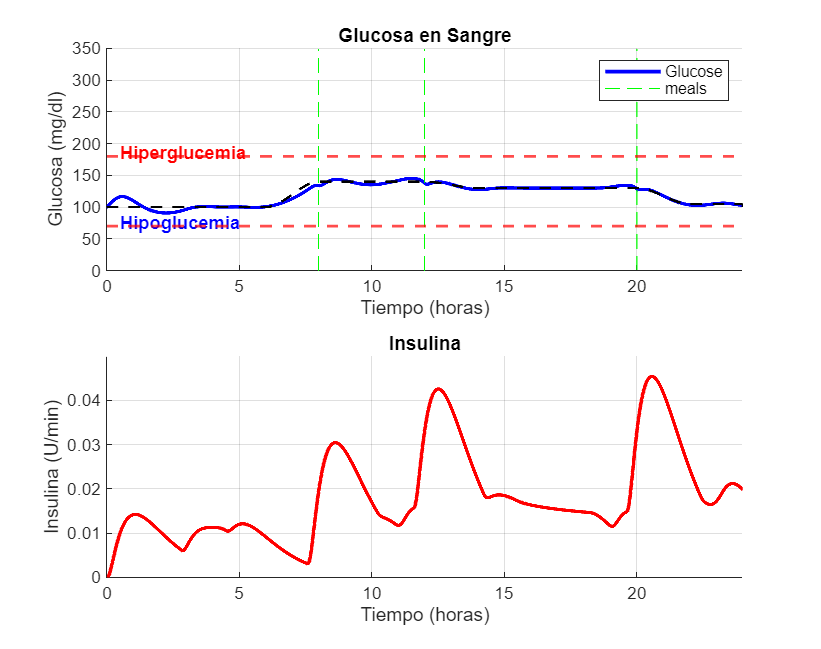

Insulina total aplicada:
   26.3999

insulina promedio:
    0.0183

IAE Norm  = 2.4817 mg/dL·min
ISE Norm  = 16.6369 (mg/dL)^2·min
ITAE Norm = 1098.3316 mg/dL·min^2

============= MÉTRICAS DE CONTROL =============
TIR    : 100.00 %
Hipo   :   0.00 %
Hiper  :   0.00 %
CV     :  13.37 %


function plot_results(results, meal_times, t_bolus)
    figure('Position',[100 100 1200 950]);
    t_hours          = results.t / 60;       
    meal_times_h     = meal_times / 60;
    bolus_times_h    = (meal_times - t_bolus) / 60;  

    subplot(2,1,1);  hold on;
    ref_curve = arrayfun(@smooth_glucose_reference, results.t);   % mg/dL
    y_lim_G   = [0 350];                                          
    area(t_hours,(results.G < 70).*results.G,...
        'FaceColor',[1 0.8 0.8],'EdgeColor','none','HandleVisibility','off');
    area(t_hours,(results.G > 180).*results.G,...
        'FaceColor',[1 1 0.6],'EdgeColor','none','HandleVisibility','off');
    hG   = plot(t_hours, results.G,'b','LineWidth',2,'DisplayName','Glucose');
    hRef = plot(t_hours, ref_curve,'--k','LineWidth',1.5,...
                'DisplayName','Referencia');
    hMeal = line([meal_times_h(1) meal_times_h(1)], y_lim_G,'Color','g',...
                 'LineStyle','--','DisplayName','meals');
    for i = 2:numel(meal_times_h)
        line([meal_times_h(i) meal_times_h(i)], y_lim_G,'Color','g',...
             'LineStyle','--','HandleVisibility','off');
    end
    yline( 70,'--r','LineWidth',1.5,'Alpha',0.7);
    yline(180,'--r','LineWidth',1.5,'Alpha',0.7);
    text(0.5,  75,'Hipoglucemia','Color','blue','FontWeight','bold');
    text(0.5, 185,'Hiperglucemia','Color','red','FontWeight','bold',...
         'HorizontalAlignment','left');
    xlim([0 24]);   ylim(y_lim_G);
    title('Glucosa en Sangre');
    xlabel('Tiempo (horas)');   ylabel('Glucosa (mg/dl)');
    legend([hG hMeal],'Location','northeast');  grid on;

    subplot(2,1,2);
    hold on;
    hI   = plot(t_hours, results.I,'r','LineWidth',2,'DisplayName','Blood Insulin');
    xlim([0 24]); ylim([0 max(results.I)*1.1]);
    title('Insulina'); xlabel('Tiempo (horas)'); ylabel('Insulina (U/min)');
    grid on;
    i_total = trapz(results.t, results.I);
    disp('Insulina total aplicada:');
    disp(i_total);

    Dtotal = results.t(end)- results.t(1);

    i_prom = i_total/Dtotal;
    disp('insulina promedio:')
    disp(i_prom);
end

main;

A lo largo de la simulación de 24 horas, el sistema de control predictivo basado en modelo (MPC) logró regular la glucosa plasmática de forma precisa y estable. En la  gráfica se observa que la concentración de glucosa sigue de manera muy cercana la referencia dinámica impuesta, manteniéndose en todo momento dentro del rango normoglucémico (entre 70 y 180 mg/dL). Esto evidencia la efectividad del controlador para anticiparse a las perturbaciones producidas por las comidas y mantener niveles estables.

En la segunda gráfica, correspondiente a la insulina plasmática, se aprecian incrementos puntuales como resultado de las decisiones del controlador. Estos pulsos de insulina se sincronizan con los horarios de las comidas, lo cual sugiere una respuesta anticipada bien planificada por parte del MPC.

Los resultados globales del sistema se resumen en la sexta gráfica de métricas de control. Se alcanza un 100% de tiempo en rango (TIR), sin presencia de hipoglucemia ni hiperglucemia. Además, el coeficiente de variación se mantiene en un 13.8%, lo que indica una excelente estabilidad en los niveles de glucosa a lo largo del día.